# **EllipticCPi**

Complementary complete elliptic integral of the third kind

## Definition


$$\Pi \mathit{\mathbf{'}}\left(\nu \left|m\right.\right)\equiv \Pi \left(\nu \left|1-m\right.\right)$$



$$\Pi \mathit{\mathbf{'}}\left(\nu ,k\right)\equiv \Pi \mathit{\mathbf{'}}\left(\nu \left|k^2 \right.\right)$$


where $\Pi \left(\nu \left|m\right.\right)$ is the complete elliptic integral of the third kind.

Domain: $\nu \le 1$ and $m\ge 0$. For the specified domain, the  codomain  is the set of real numbers.

Basic features:

Special values:

$\Pi \left(-\infty \left|m\right.\right)=0$,    $\Pi \left(0\left|m\right.\right)=\mathit{K'}\left(m\right)$,   $\Pi \left(1\left|0\right.\right)=\infty$


$$\Pi \left(\nu \left|1\right.\right)=\frac{\pi }{2\sqrt{1-m}}$$


Identities:

## Syntax

Y = EllipticCPi(X,K)

y = elCPi(x,k)

Y = mEllipticCPi(X,M)

y = melCPi(x,m)

## Description

**Y = EllipticCPi(X,K)** returns the complementary complete elliptic integral of the third kind for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **EllipticCPi** is the wrapper function which calls the functions **elCPi** element-wise via the function **ufun2**.

**y = elCPi(x,k)** returns the value of the complementary complete elliptic integral of the third kind for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **elCPi** is the wrapper function which calls the functions **melCPi**.

**Y = mEllipticCPi(X,M)** returns the complementary complete elliptic integral of the third kind for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mEllipticCPi** is the wrapper function which calls the functions **melCPi** element-wise via the function **ufun2**.

**y = melCPi(x,m)** compute value of the complementary complete elliptic integral of the third kind for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **melCPi **call the Carlson's function **rf **and **rj ** for calculation of $\Pi \mathit{\mathbf{'}}\left(\nu \left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
[elCPi(x,k), EllipticCPi(x,k), melCPi(x,k^2), mEllipticCPi(x,k^2)]

ans =    3.234773471249465   3.234773471249465   3.234773471249465   3.234773471249465


Accuracy.

fprintf('%.16g\n',elCPi(0.5,1.2)) 

1.992452045402445


%  Maple  1.992452045402444_11

Maple help

fprintf('%.10g\n',elCPi(0.2,0.3))

3.032020785


%Maple 3.032020785

[MATLAB example](https://www.mathworks.com/help/symbolic/ellipticcpi.html)

format short
s = [mEllipticCPi(-1, 1/3), mEllipticCPi(0, 1/2),...
  mEllipticCPi(9/10, 1), mEllipticCPi(-1, 0)]

s =     1.3703    1.8541    4.9673       Inf


fprintf('%.10g %.10g %.10g %.10g\n',s)

1.370337322 1.854074677 4.967294133 Inf


Special values

melCPi(1,0)

ans = Inf

m = 3; % m > 0
disp(melCPi(0,m) - melCK(m)) 

     0



m = 2;
melCPi(-inf,m)

ans = 0

nu = -2;
disp(melCPi(nu,1) - pi/2/sqrt(1-nu)) 

     0



**Vector input**

nu = [0.1, 0.5, 0.89, 0.99995];
disp(EllipticCPi(nu,1)-pi/2./sqrt(1-nu))

     0     0     0     0



**Matrix input**

nu = [0.1, 0.5, 0.89; -0.1, -0.97, 0.99995 ]';
disp(EllipticCPi(nu,ones(size(nu)))-pi/2./sqrt(1-nu))

     0     0
     0     0
     0     0



## **Plot **

**Example 1**

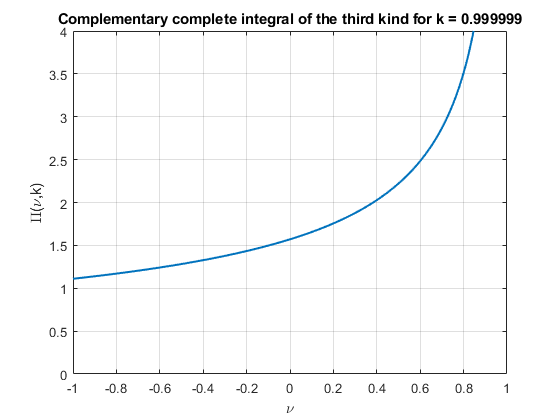

figure
x=-1:0.01:1;
k = 0.999999;
plot(x,EllipticCPi(x,k),'LineWidth',1.5)
xlabel('\nu')
ylabel('\Pi(\nu,k)')
%xlim([-1.1 1.1])
ylim([0 4])
title(sprintf('Complementary complete integral of the third kind for k = %g',k))
grid on

**Example 2**

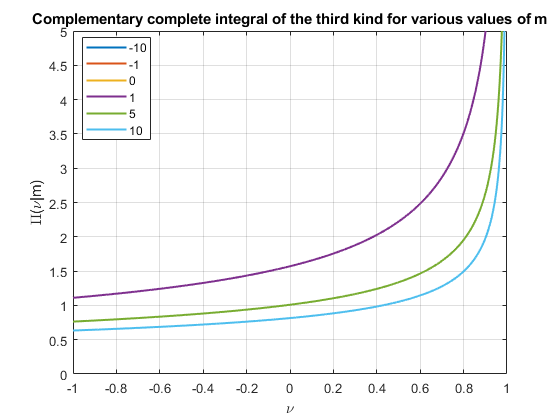

figure
X = -1:0.001:1;
M = [-10,-1,0,1,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mEllipticCPi(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) 0 5])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Complementary complete integral of the third kind for various values of m')
xlabel('\nu')
ylabel('\Pi(\nu|m)')

**Example 3**

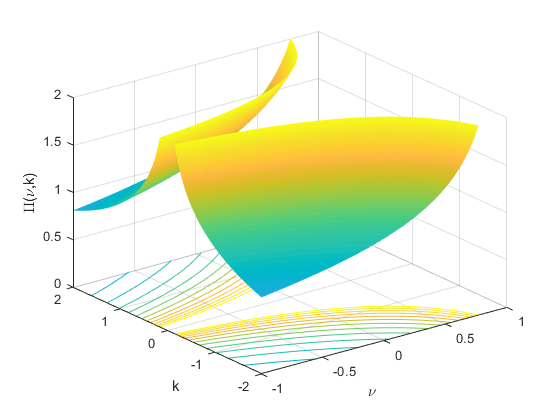

figure
x=-1:0.01:1;
k=-2:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,EllipticCPi(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:0.1:2;
caxis([0 2])
view(3);
xlabel('\nu')
ylabel('k')
zlabel('\Pi(\nu,k)')
zlim([0 2])
grid on

**Example 4**

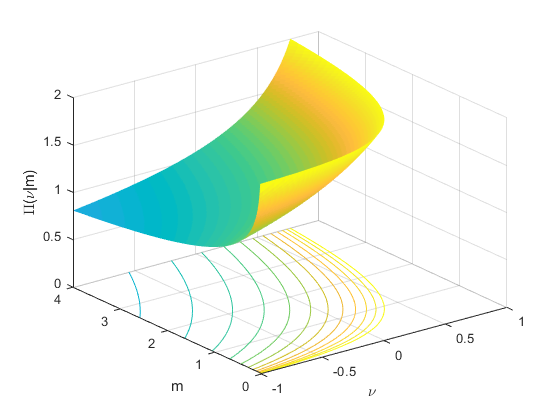

figure
x=-1:0.01:1;
m=0:0.01:4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mEllipticCPi(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:0.1:2;
view(3)
caxis([0 2])
xlabel('\nu')
ylabel('m')
zlabel('\Pi(\nu|m)')
zlim([0 2])
grid on

**Example 5**

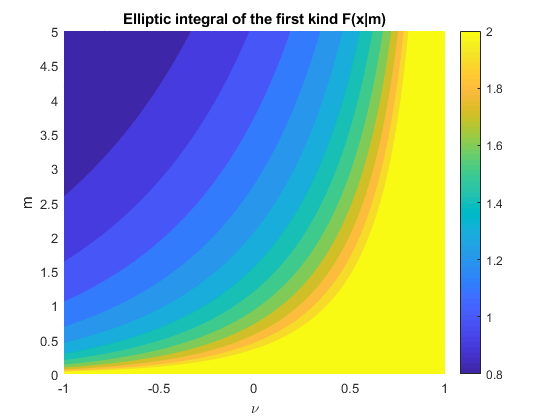

figure
f = @(x,m)mEllipticCPi(x,m);
fcontour(f,[-1 1 0 5],'Fill','on','LevelList',0:0.1:2,'MeshDensity',200)
title('Elliptic integral of the first kind F(x|m)')
colorbar
xlabel('\nu')
ylabel('m')
grid on

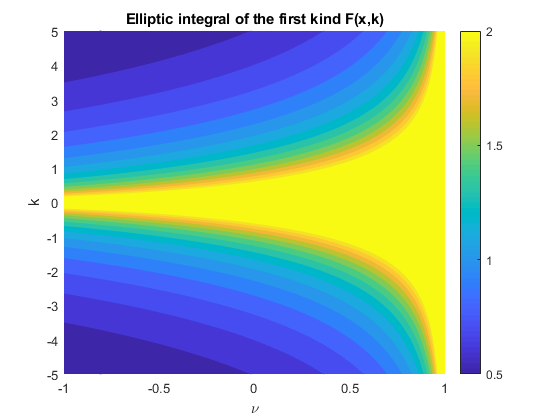

figure
f = @(x,k)EllipticCPi(x,k);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',0:0.1:2,'MeshDensity',200)
title('Elliptic integral of the first kind F(x,k)')
colorbar
xlabel('\nu')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also